syms  Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t) Hit(t)

syms lambda beta_m mu_m theta_m mu_h beta_h theta_h...
    gamma_h

H = Hs + He + Hi + Hr;
M = Ms + Me + Mi;

ode1 = diff(Ms) == lambda - beta_m * Hi * Ms/H - mu_m * Ms;
ode2 = diff(Me) == beta_m * Hi * Ms/H - (theta_m + mu_m) * Me;
ode3 = diff(Mi) == theta_m * Me - mu_m * Mi;
ode4 = diff(Hs) == - beta_h * Mi * Hs/M + (He + Hi + Hr) * mu_h;
ode5 = diff(He) == beta_h * Mi * Hs/M - (theta_h + mu_h) * He;
ode6 = diff(Hi) == theta_h * He - (gamma_h + mu_h) * Hi;
ode7 = diff(Hr) == gamma_h * Hi - mu_h * Hr;
ode8 = diff(Hit) == theta_h * He;

odes = [ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8];
vars = [Hit Hi Me Hr Hs He Ms Mi];

opts = odeset('NonNegative',1:8);

Range1 = [17 17             %Hit0
          17 17             %Hi    
          0	100             %Me
          0 100             %Hr
          50000	250000      %Hs
          0	1000            %He
          0	120000          %Ms
          0	100             %Mi
         ];
     
Range2 = [0	4           %beta_h
          0	4           %beta_m
          0.4	1.8     %gamma_h
          0	42694       %Lambda
          0.0004 0.0004 %mu_h
          0.01 0.6      %mu_m   
          0.7	1.75    %theta_h
          0.58	0.88    %tetha_m
        ];     

Range = [Range1; Range2];

ParNames = {'\lambda'; '\beta_m'; '\mu_m'; '\theta_m'; '\beta_h'; '\theta_h'; '\gamma_h'};
VarNames = {'M_e(0)'; 'H_r(0)'; 'H_s(0)'; 'H_e(0)'; 'M_s(0)'; 'M_i(0)'};

FullNames = [VarNames;ParNames];

Finally, use the gsua_dpmat to create the functional table

load("../Dengue/Itagui.mat")

ydata = Itagui(1:40)';

D = length(ydata);
Domain = [0 D-1];
xdata = 0 : D-1;

[T,~] = gsua_dpmat(odes,vars,[0 D-1],'Model','output',2,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

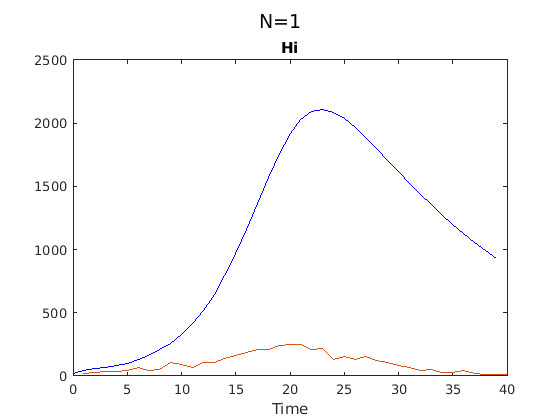

Estimations = readmatrix("DengueIntervals.csv");
Estimations = Estimations(2:end,:);

T.Nominal = Estimations(:,1);
T.Range = Estimations(:,2:3);

gsua_eval(T.Nominal,T);
hold on
plot(ydata)

Progress: 100%
Estimated processing time (h:m:s): 0:0:2
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:2
Estimated stop time (h:m:s): 16:30:46
Number of simulations: 1000


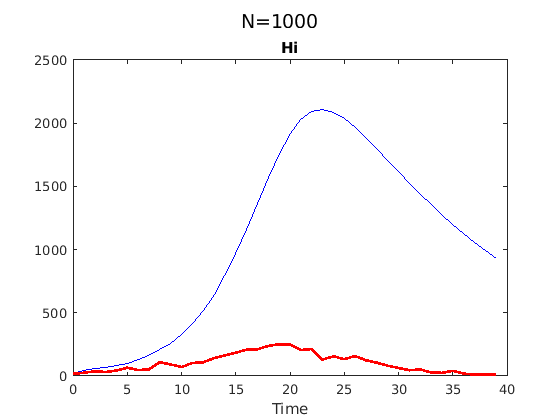

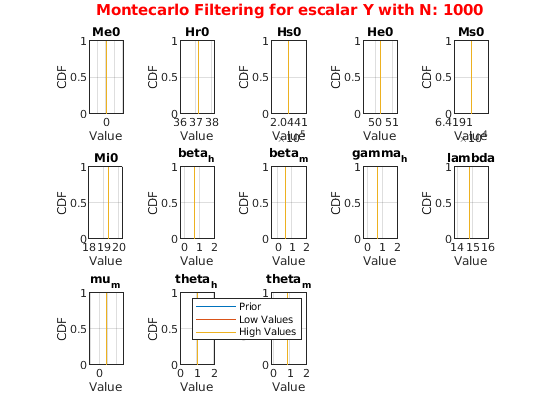


N = 1000;
M = gsua_dmatrix(T,N,'Method','Sobol');
gsua_ua(M, T,'xdata', xdata, 'ynom', ydata, 'parallel', false);

load('Amazonas.mat');

Error using load
Unable to find file or directory 'Amazonas.mat'.


ydata = ydata(:, 10:end)';
ydata = [ydata(:,3), ydata(:,2), ydata(:,1)];

D = length(ydata);
Domain = [0 D-1];
xdata = 0 : D-1;

clf
plot(ydata, '-o', 'LineWidth',1.5)
xlim([0 90])
title('Number of cases of COVID-19 in Amazonas-Colombia')
ylabel('Number of cases')
xlabel('Time (days)')
grid on
legend({'Recovered','Dead','Infected'},"Location","best")

**Create the model as a table for GSUA-CSB toolbox implementation**

First, define the model as a symbolic structure

syms S(t) I(t) R(t) D(t) A(t) E(t) Q(t) C(t)
syms alpha beta delta eta tau epsilon mu gamma k lambda nu z sigma

N = S + C + E + A + I + Q + R + D;

ode1 = diff(S) == -alpha*S - beta*I/N*S - sigma*S*A/N - eta*S;
ode2 = diff(A) ==  -tau*A + epsilon*E;
ode3 = diff(C) == alpha*S - mu*C;
ode4 = diff(E) == -gamma*E + beta*I/N*S + mu*C + eta*S + sigma*S*A/N - epsilon*E;
ode5 = diff(I) == tau*A + gamma*E - delta*I;
ode6 = diff(R) == lambda*Q;
ode7 = diff(Q) == delta*I - lambda*Q - k*Q;
ode8 = diff(D) == k*Q;

odes = [ode1; ode2; ode3; ode4; ode5; ode6; ode7; ode8];
vars = [R D I S A C E Q];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [  ydata(1,1) ydata(1,1);  %R
            ydata(1,2) ydata(1,2);  %D    
            ydata(1,3) ydata(1,3);  %I
            7600 80000;      %S
            0 2000;               %A
            0 1000;              %C
            0 2000;               %E
            0 2000              %Q
];

Range2 = [  0 2;    %alpha
            0 10;   %beta  
            0 1;    %delta
            0 5;    %epsilon
            0 1;    %eta
            0 1;    %gamma
            0 1;    %k
            0 1;    %lambda
            0 1;    %mu
            0 10;   %sigma    
            0 6;    %tau
]; 

Range = [Range1; Range2];


Finally, use the gsua_dpmat to create the functional table

outs = [1, 3];
% outs = [3];
[T,~] = gsua_dpmat(odes,vars,[0 length(xdata)],'Model','output',outs,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccccccccccccccccc} R\left(t\right) & \text{D}\left(t\right) & \text{I}\left(t\right) & S\left(t\right) & A\left(t\right) & C\left(t\right) & \text{E}\left(t\right) & Q\left(t\right) & \alpha & \beta & \delta & \epsilon & \eta & \gamma & k & \lambda & \mu & \sigma & \tau \end{array}\right)$$

Progress: 100%
Estimated processing time (h:m:s): 0:0:5
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:5
Estimated stop time (h:m:s): 15:19:47
Number of simulations: 1000


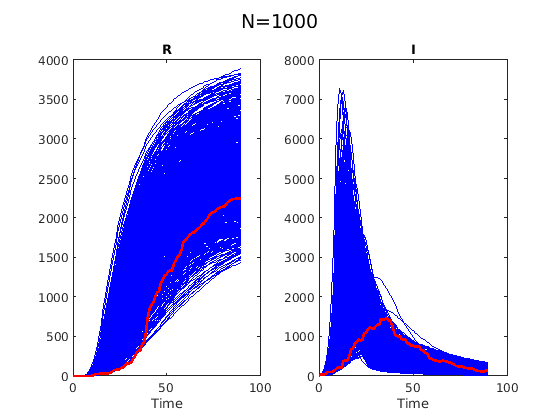

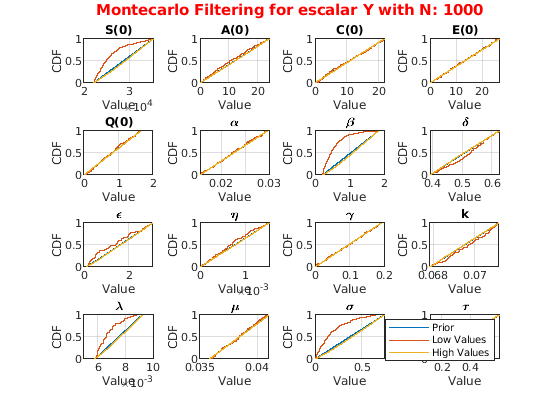

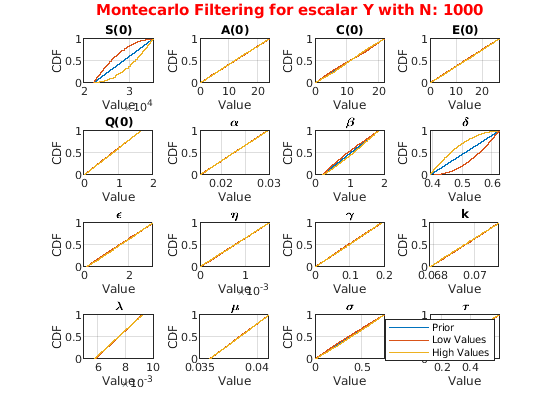

T.Row = ["S(0)", "A(0)", "C(0)", "E(0)", "Q(0)",...
    "\alpha", "\beta", "\delta", "\epsilon", "\eta", "\gamma", "k", "\lambda", "\mu", "\sigma",  "\tau"];

Estimations = readmatrix("COVIDIntervals.csv");
Estimations = Estimations(2:end,:);

T.Nominal = Estimations(:,1);
T.Range = Estimations(:,2:3);

N = 1000; 
M = gsua_dmatrix(T,N,'Method','Sobol');
gsua_ua(M, T,'xdata', xdata, 'ynom', ydata(:,outs)', 'parallel', false);

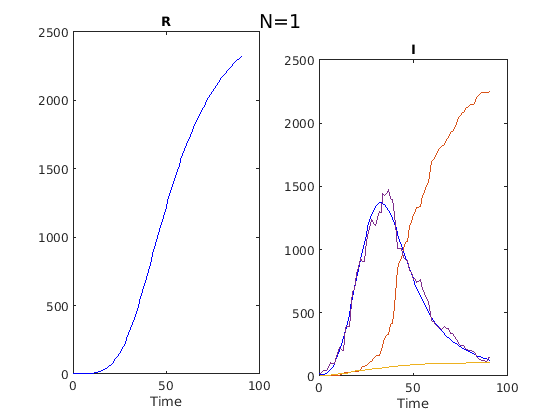

gsua_eval(T.Nominal,T);
hold on 
plot(ydata)